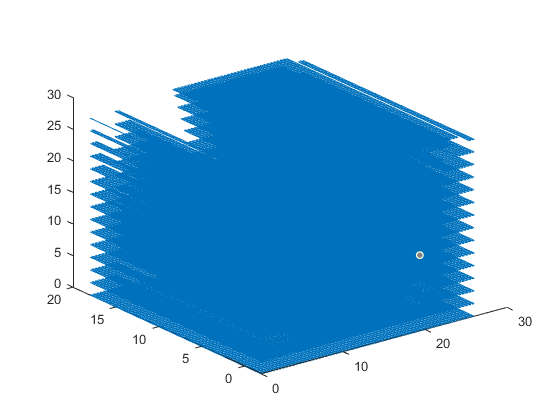

clear all;
stl = stlread("Test Objects\disgustingShape.stl");
% stl = stlTransform(stl,90,0,0,0,0,0,100);
sliceGen = FlatUniformSliceGenerator(stl,2);
infillPath = createInfillLayer(sliceGen,0.2);
plot3(infillPath(:,1),infillPath(:,2),infillPath(:,3));
view(3);